# `Clear Section`

clear           
clc
close all

# `Generate Ensample`

A=4;                                                                    % Amplitude Value
number_of_enamples=500;                                                 % total number of Realizations
number_of_bits=100;                                                     % number of bits in each Realization
number_of_samples_per_bit=7;                                            % number of samples for each bit
number_of_samples=number_of_bits*number_of_samples_per_bit;             % total number of samples for each Realization
Total_Transmitted_Data=zeros(number_of_enamples, number_of_samples-1);  % hold transmitted data
td_for_first_relialization = 0;
for i = 1 : number_of_enamples
    if i == 1
        [Total_Transmitted_Data, td_for_first_relialization] = Generate_Random_Data();
else
    Total_Transmitted_Data = [Total_Transmitted_Data; Generate_Random_Data()];
    end
end

# `Plot Waveforms`

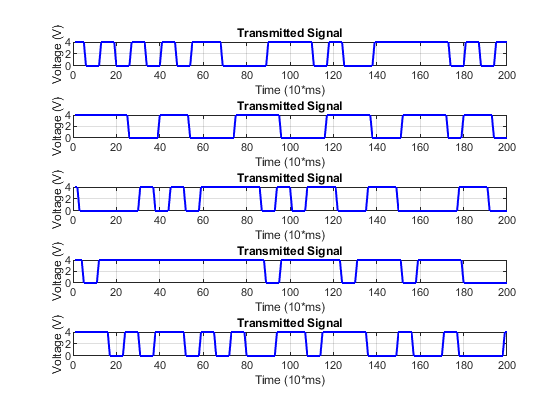

time=(1:1:number_of_samples);
figure
for i = 1 : 5
    subplot(5,1,i)
    plot(time, Total_Transmitted_Data(i,:), 'b', "LineWidth",1.5)
    xlabel("Time (10*ms)")
    ylabel("Voltage (V)")
    title("Transmitted Signal")
    grid on
    xlim([0 200])
end

# `Calculate Statistical Mean`

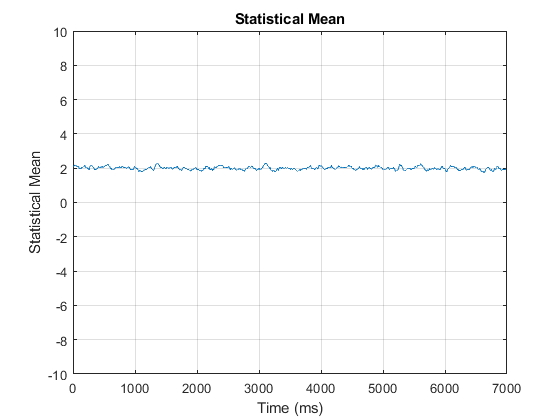

Statistical_Mean = sum(Total_Transmitted_Data)/number_of_enamples;
% Statistical_Mean = mean(Total_Transmitted_Data);
figure
plot(0:10:(number_of_samples-1)*10,Statistical_Mean)
grid on
xlabel("Time (ms)")
ylabel("Statistical Mean")
title("Statistical Mean")
ylim([-10 10])

# `Calculate Statistical AutoCorrelation function (ACF)`

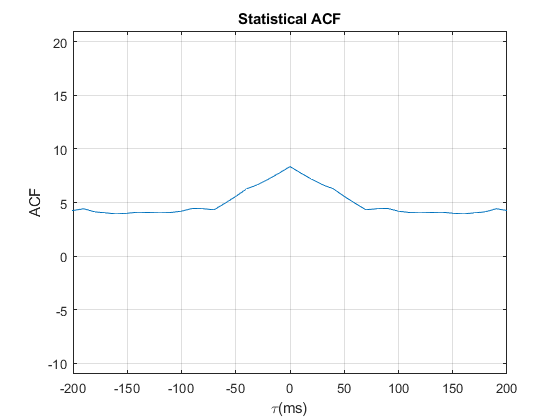

% result=0;
average=zeros(1, number_of_samples);  % 1x700 
for i = 1 : number_of_samples
    average(1,i) = mean(Total_Transmitted_Data(:,1) .* Total_Transmitted_Data(:,i));
end
average=[fliplr(average(1, 2:end)) average];
figure
plot(((-number_of_samples+1)*10:10:(number_of_samples-1)*10), average)
grid on
xlabel("\tau(ms)")
ylabel("ACF")
title("Statistical ACF")
xlim([-200 200])
ylim([-A^2+5 A^2+5])

# `Calculate PSD`

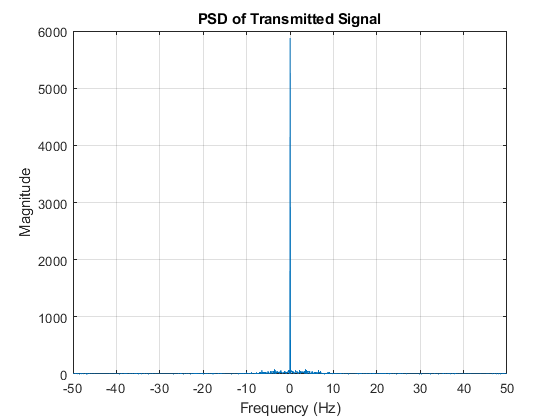

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
PSD = fftshift(fft(average));
N = length(PSD);                                % Number of samples
Ts=0.01;                                        % sample bit every 10ms
Fs=1/Ts;                                        % sampling frequency
freq = (-N/2+1:N/2)*(Fs/(N));                   % Frequency axis (Hz)
figure
plot(freq, abs(PSD));                 
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('PSD of Transmitted Signal');
grid on

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# `Calculate Time Average Mean`

% Time_Mean = zeros(1, number_of_enamples);
realization_number=1;  % change it from 1 to number_of_enamples
Time_Mean=mean(Total_Transmitted_Data(realization_number,:));
fprintf("Time Average Mean: %f", Time_Mean);

Time Average Mean: 1.920000

# `Calculate Time Average Autocorrelation`

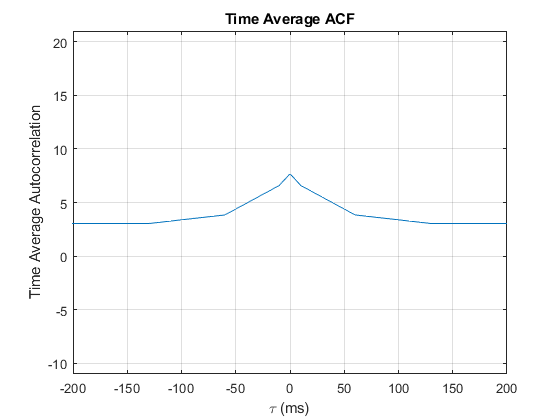

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1=Total_Transmitted_Data(1, :);
Time_Auto_Corr= zeros(1, number_of_samples);
result=0;
for i = 1 : number_of_samples
    if i == 1
        x2 = x1;
    else
        x2=[x1(i+1: number_of_samples), x1(1:i)];
    end
    result =x1.*x2;
    Time_Auto_Corr(i)=sum(result)/length(result);
end

Time_Auto_Corr=[fliplr(Time_Auto_Corr(1, 2:end)) Time_Auto_Corr];
figure
plot(((-number_of_samples+1)*10:10:(number_of_samples-1)*10), Time_Auto_Corr)
grid on
xlabel("\tau (ms)")
ylabel("Time Average Autocorrelation")
title("Time Average ACF")
xlim([-200 200])
ylim([-A^2+5 A^2+5])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# `Generate Random Data`

function [data_transmitted, td] = Generate_Random_Data()
A=4;                                        % Amplitude Value
number_of_bits=100;                         % number of bits in each realization
number_of_samples=7;                        % number of samples for each bit
data=randi(2,[1,number_of_bits+1])-1;       % generate 1x100 random numbers '0' or '1' 
%%%%%%%% change this line according to line coding %%%%%%%%
choose = 2;                                   % choose which line code to use (1. polar NRZ, 2. unipolar NRZ, 3. polar RZ)
switch choose
    case 1
        data=(2*data-1)*A;                          % mapping to A & -A (Polar NRZ)
        data=repmat(data, number_of_samples, 1);    % repeat each bit 7 times to sample DAC every 10ms
    case 2
        data=data*A;                                % mapping to A & 0  (Unipolar NRZ)
        data=repmat(data, number_of_samples, 1);    % repeat each bit 7 times to sample DAC every 10ms    
    case 3
        data=NR_line_code(data, A, number_of_bits); % mapping           (Polar RZ)
    otherwise
        disp("invalid line code choose");
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
data=data(:);                               % convert data to column vector 700x1

### `Generate random time shift`

if choose ~= 3
    td=randi(number_of_samples)-1;              % generate random number from 0 to 6
else
    td=randi(4)-1;                              % generate random number from 0 to 3
end

### `Concatenate with Random Data`

data_transmitted = (data(td+1:700+td))';    % window data from td to 700+td (700 samples)
end

### `polar NR line code function`

function out = NR_line_code(data, A, number_of_bits)
    out = (2*data-1)*A;
    out = repmat(out, 4 ,1);
    out = [out; zeros(3, number_of_bits+1)];
end